Сохрание данных из файлов в переменные

spectra = importdata('spectra.csv');
starNames = importdata('star_names.csv');
lambdaStart = importdata('lambda_start.csv');
lambdaDelta = importdata('lambda_delta.csv');

Определим константы

lambdaPr = 656.28; %нм
speedOfLight = 299792.458; %км/c

Количество измерений для одной звезды

nObs = size(spectra,1);

Количество исследуемых звезд

nStars = size(spectra,2);

Получение вектора длин волн

lambdaEnd = lambdaStart+(nObs-1)*lambdaDelta;
lambda = (lambdaStart : lambdaDelta : lambdaEnd)';

Получение вектора скоростей

speed = linspace(0,0,nStars);
sHa = linspace(0,0,nStars);
idx = linspace(0,0,nStars);
lambdaHa = linspace(0,0,nStars);
z = linspace(0,0,nStars);
for i = 1 : 1 : nStars
    [sHa(i), idx(i)]= min(spectra(:,i));
    lambdaHa(i) = lambda(idx(i));
    z(i) = (lambdaHa(i) / lambdaPr) - 1;
    speed(i) = z(i) * speedOfLight;
end
speed=speed';

Построение графиков

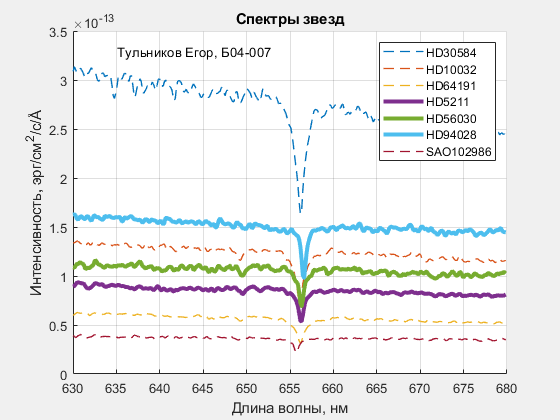

fg1 = figure;
set(fg1, 'Visible', 'on')
xlabel('Длина волны, нм')
ylabel(['Интенсивность, эрг/см^2/с/', char(197)])
title('Спектры звезд')
hold on
for j = 1 : 1 : nStars
    if z(j) > 0
        plot(lambda, spectra(:,j),'-','LineWidth',3)
    end
    if z(j) < 0
        plot(lambda, spectra(:,j),'--','LineWidth',1)
    end
end
legend(starNames)
grid On
text(lambdaStart + 5, max(max(spectra)) * 1.05,'Тульников Егор, Б04-007')
hold off

Звезды, удаляющиеся от земли

movaway=starNames(speed'>0);

Сохранение графика

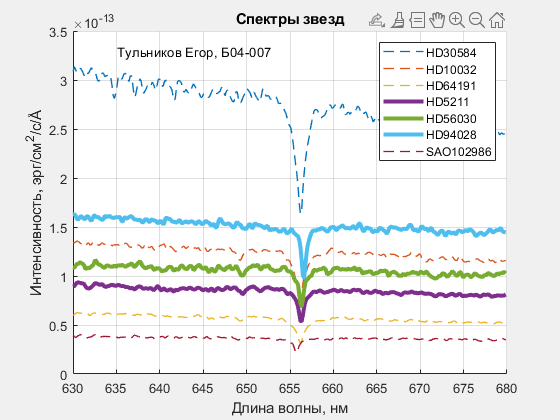

saveas(fg1,'spectra.png')